 Define the stimuli 

fs = 48828;
folder_name = '/media/alex/5FC39EAD5A6AA312/Dory_18_04_18/Dory_18_04_2018_Stimuli/reverb_with_noise_stimuli/';
metadata_path = [folder_name 'wav_files/alexreverbmetadata'];
load(metadata_path);
[num_rep,num_cond] = size(alexreverbmetadata);

for stim = 1:numel(alexreverbmetadata)
    noise_mat(stim) = alexreverbmetadata(stim).hasnoise;
end
noise_mat = reshape(noise_mat,num_rep,num_cond);
ix_nonoise_as1 = find(noise_mat(:,1) == 0);
ix_nonoise_as1 = [ix_nonoise_as1(1) 1];
ix_nonoise_as2 = find(noise_mat(:,4) == 0);
ix_nonoise_as2 = [ix_nonoise_as2(1) 4];
ix_nonoise_r1s1 = find(noise_mat(:,2) == 0);
ix_nonoise_r1s1 = [ix_nonoise_r1s1(1) 2];
ix_nonoise_r1s2 = find(noise_mat(:,5) == 0);
ix_nonoise_r1s2 = [ix_nonoise_r1s2(1) 5];
ix_nonoise_r2s1 = find(noise_mat(:,3) == 0);
ix_nonoise_r2s1 = [ix_nonoise_r2s1(1) 3];
ix_nonoise_r2s2 = find(noise_mat(:,6) == 0);
ix_nonoise_r2s2 = [ix_nonoise_r2s2(1) 6];

stimlist{1} = [folder_name alexreverbmetadata(ix_nonoise_as1(1),ix_nonoise_as1(2)).stimname];
stimlist{2} = [folder_name alexreverbmetadata(ix_nonoise_as2(1),ix_nonoise_as2(2)).stimname];
stimlist{3} = [folder_name alexreverbmetadata(ix_nonoise_r1s1(1),ix_nonoise_r1s1(2)).stimname];
stimlist{4} = [folder_name alexreverbmetadata(ix_nonoise_r1s2(1),ix_nonoise_r1s2(2)).stimname];
stimlist{5} = [folder_name alexreverbmetadata(ix_nonoise_r2s1(1),ix_nonoise_r2s1(2)).stimname];
stimlist{6} = [folder_name alexreverbmetadata(ix_nonoise_r2s2(1),ix_nonoise_r2s2(2)).stimname];


save_dir = '/home/alex/Desktop/Reverb_pics/';

Get the cochleagrams for the stimuli

for stim = 1:numel(stimlist)
    filename = stimlist{stim};
    [data_l_r{stim},fs] = audioread(filename);
    data_both{stim} = [data_l_r{stim}(:,1);data_l_r{stim}(:,2)];
    example_coch(data_both{stim},fs);
    save_name = [save_dir,num2str(stim),'_coch.png'];
    export_fig(save_name);
    close;
end

Plot the waveform

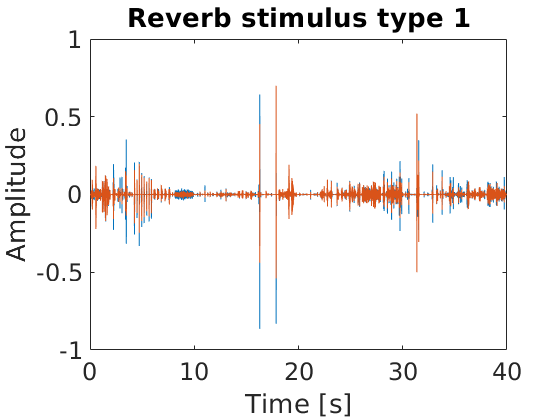

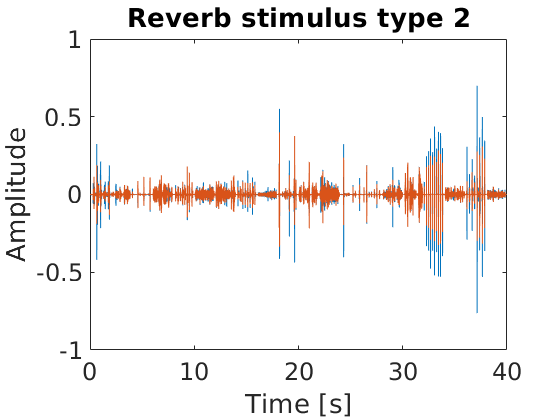

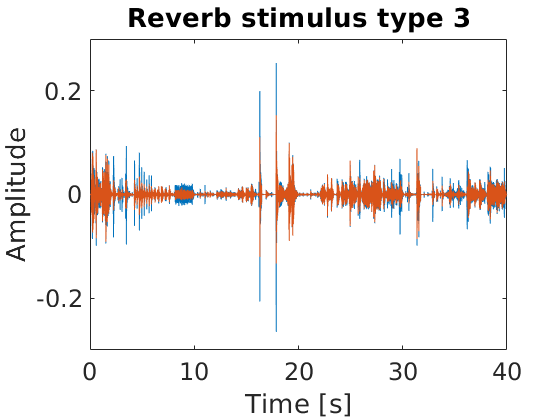

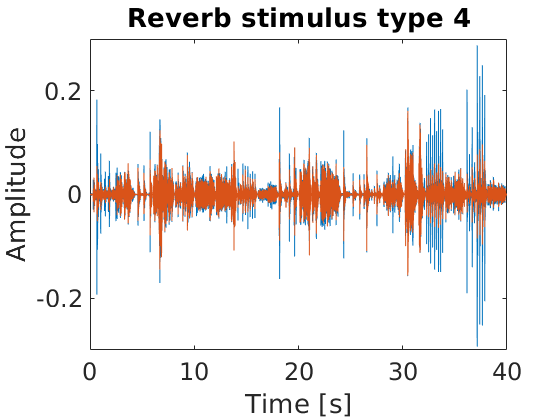

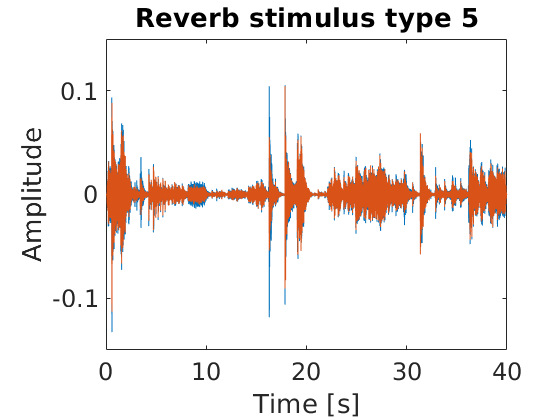

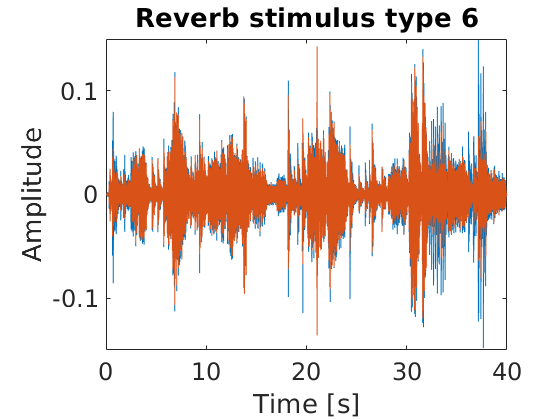

for stim = 1:6
    time_s = [1/fs:1/fs:40];
    figure;
    plot(time_s,data_l_r{stim});
    xlabel('Time [s]');
    ylabel('Amplitude');
    title(['Reverb stimulus type ' num2str(stim)]);
    set(findall(gcf,'-property','FontSize'),'FontSize',18);
end

Calculate the loudness across conditions 

data_l_anech = [data_l_r{1}(:,1);data_l_r{2}(:,1)];
data_r_anech = [data_l_r{1}(:,2);data_l_r{2}(:,2)];
data_both_anech = [data_both{1};data_both{2}];
data_l_reverb1 = [data_l_r{3}(:,1);data_l_r{4}(:,1)];
data_r_reverb1 = [data_l_r{3}(:,2);data_l_r{4}(:,2)];
data_both_reverb1 = [data_both{3};data_both{4}];
data_l_reverb2 = [data_l_r{5}(:,1);data_l_r{6}(:,1)];
data_r_reverb2 = [data_l_r{5}(:,2);data_l_r{6}(:,2)];
data_both_reverb2 = [data_both{5};data_both{6}];

db_level_l_anech = db_calc(data_l_anech);
db_level_r_anech = db_calc(data_r_anech);
db_level_anech = db_calc(data_both_anech);
db_level_l_reverb1 = db_calc(data_l_reverb1);
db_level_r_reverb1 = db_calc(data_r_reverb1);
db_level_reverb1 = db_calc(data_both_reverb1);
db_level_l_reverb2 = db_calc(data_l_reverb2);
db_level_r_reverb2 = db_calc(data_r_reverb2);
db_level_reverb2 = db_calc(data_both_reverb2);


Calculate the loudness using a sliding window

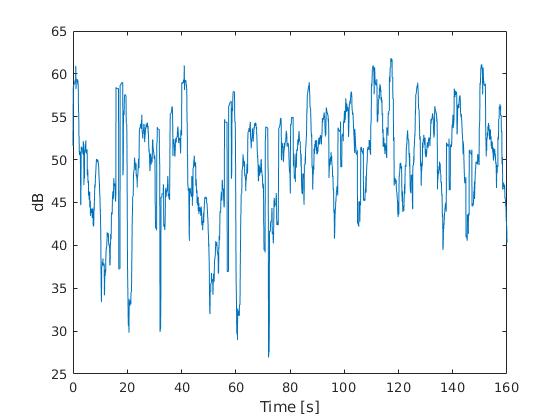

t_window_ms = 1000;
t_window_s = t_window_ms/1000;
[dB_cont_anech] = db_conv_calc(data_both_anech,t_window_s,fs);

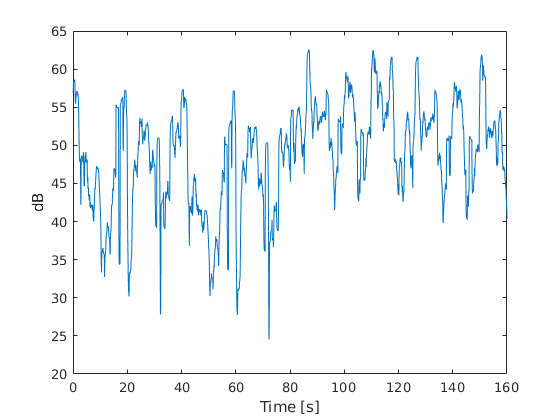

[dB_cont_reverb1] = db_conv_calc(data_both_reverb1,t_window_s,fs);

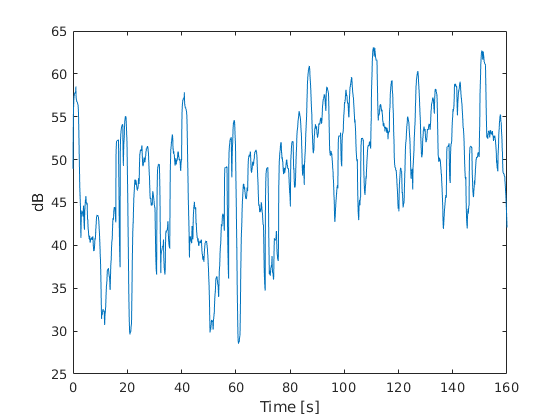

[dB_cont_reverb2] = db_conv_calc(data_both_reverb2,t_window_s,fs);